# Predictive Control for Cobot Safety

*Could add in a short introductory description of the aims of the project and such*

## Robot Plant and Initial Conditions

Load the KINOVA Gen 3 robot manipulator multibody model and rigid body tree.

clear; clc;
[robotRBT, robotInformation] = loadrobot("kinovaGen3", "DataFormat", "column", "Gravity", [0 0 -9.81]);

Define key robot parameters that will be used further on. The quantity of joints and the end-effector (tool) element of the rigid body tree.

joint_qty = numel(homeConfiguration(robotRBT));
endEff = 'EndEffector_Link';

Prepare inverse kinematic equations to compute robot configurations given end-effector poses.

robot_InverseKinematics = inverseKinematics("RigidBodyTree", robotRBT);
robot_InverseKinematics.SolverParameters.AllowRandomRestart = false;
weights = [1 1 1 1 1 1];

Define initial and final trajectory task-space coordinates. The initial position may be given as a complete robot configuration while the final position is a desired end-effector pose (other joint positions in the task-space are irrelevant).

qInit = [0 0 0 0 0 0 0]'*pi/180; % initial joint configuration in radians
taskInit = getTransform(robotRBT, qInit, endEff); % initial transformation matrix of task
coordStart = taskInit(1:3, 4); % initial task-space end-effector coordinates XYZ

taskEnd = trvec2tform([0.6 0.4 0.3])*axang2tform([0 1 0 pi]); % final task-space end-effector coordinates XYZ
anglesEnd = rotm2eul(taskEnd(1:3, 1:3), "XYZ"); % final task-space end-effector rotational coordinates [phi theta psi]
poseEnd = [taskEnd(1:3, 4); anglesEnd']; % final pose vector [X Y Z phi theta psi]

## Static and Dynamic Obstacles

Static obstacle generation.

% obstacle representing the floor of the environment space
obst_floor = collisionBox(2.0, 2.0, 0.04);
obst_floor.Pose = trvec2tform([0.5 0 -0.02]);

% obstacle to represent the surface of a table
obst_tableTop = collisionBox(0.5, 2.0, 0.1);
obst_tableTop.Pose = trvec2tform([0.5 0 0.2]);

% obstacles to represent the table legs
obst_tableLeg1 = collisionBox(0.2, 0.1, 0.65);
obst_tableLeg1.Pose = trvec2tform([0.5 0.8 0.325]);

obst_tableLeg2 = collisionBox(0.2, 0.1, 0.65);
obst_tableLeg2.Pose = trvec2tform([0.5 -0.8 0.325]);

% obstacle to represent shelf
obst_shelf = collisionBox(0.4, 2.0, 0.05);
obst_shelf.Pose = trvec2tform([0.5 0 0.65]);

% single element containing all the static obstacles to compress code
staticObst = {obst_floor, obst_tableTop, obst_tableLeg1, obst_tableLeg2, obst_shelf};

Dynamic obstacle generation.

[obst_robot, ~] = loadrobot("kinovaGen3", "DataFormat", "column");

% obstacle robot inverse kinematics
obst_robot_InverseKinematics = inverseKinematics("RigidBodyTree", obst_robot);
obst_robot_InverseKinematics.SolverParameters.AllowRandomRestart = false;

% obstacle robot end-effector task-space coordinates transformation matrix
obst_robot_coord = trvec2tform([0.6 0.4 0.3])*axang2tform([0 1 0 pi]);

% obstacle robot initial configuration
obst_robot_config = obst_robot_InverseKinematics(endEff, obst_robot_coord, weights, homeConfiguration(obst_robot));
obst_robot_config = wrapToPi(obst_robot_config);

## Initial Visualization

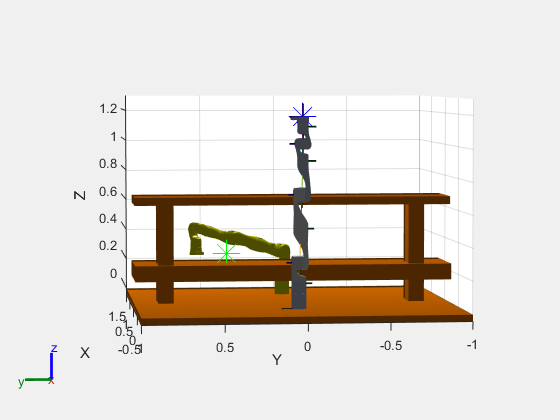

figure('Name', 'Initial Robot and Obstacle Conditions');

% display the robot rigid body tree at the initial joint configuration
show(robotRBT, qInit(:, 1), 'PreservePlot', false, 'Frames', 'on');
axis([-0.5 1.5 -1.0 1.0 -0.04 1.3])
view([-90 10 5]);
hold on

% display a marker of the starting end-effector position
plot3(coordStart(1), coordStart(2), coordStart(3), 'b*', 'MarkerSize', 20);

% display a marker of the final end-effector position
plot3(poseEnd(1), poseEnd(2), poseEnd(3), 'g*', 'MarkerSize', 20);

% display static obstacles
for i=1:length(staticObst)
    [~, posObs] = show(staticObst{i});
end

% display dynamic obstacles
obst_dynamic = show(obst_robot, obst_robot_config, 'PreservePlot', false, 'Frames', 'off', 'Position', [1 0 0 pi/2]);
for i=1:(joint_qty+1)
    obst_dynamic.Children(i).FaceColor = 'y';
end

## Design: PID Control

### Closed-Loop Trajectory Planning

### Joint-Space Simulation

### Final Visual Simulation

## Design: Linear MPC

### Closed-Loop Trajectory Planning

### Joint-Space Simulation

### Final Visual Simulation

## Design: Non-linear MPC

### Closed-Loop Trajectory Planning

### Joint-Space Simulation

### Final Visual Simulation